# MAE 384 Group Project

### Team: Sicko Code

### Contributors: Hayden Redmond, Ottavia Formicone, Brady Bauer, Ava Masche

## Part 1: Modeling disease spread using SIR model

            
$$\begin{array}{l}
\textrm{Susceptible}\;\textrm{individuals}:\;\frac{\textrm{dS}\left(t\right)}{\textrm{dt}}=-\frac{\beta }{N}S\left(t\right)I\left(t\right)\\
\textrm{Infected}\;\textrm{individuals}:\;\;\;\;\;\;\;\;\;\frac{\textrm{dI}\left(t\right)}{\textrm{dt}}=\frac{\beta }{N}S\left(t\right)I\left(t\right)-\gamma I\left(t\right)\\
\textrm{Recovered}\;\textrm{individuals}:\;\;\;\frac{\textrm{dR}\left(t\right)}{\textrm{dt}}=\gamma I\left(t\right)\\
\textrm{Total}\;\textrm{population}:\;\;\;\;\;\;\;\;\;\;\;\;\;\;N=S\left(t\right)+I\left(t\right)+R\left(t\right)\\
\\
\beta =\textrm{transmission}\;\textrm{rate}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\gamma =\textrm{recovery}\;\textrm{rate}
\end{array}$$


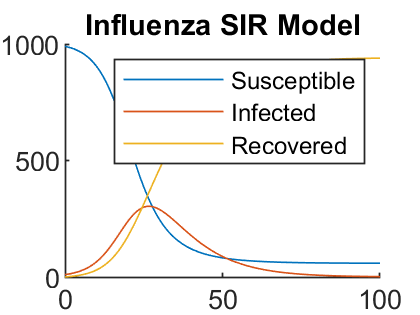

clear; clc; close all
Influenza_Tran_Rate = 0.3;
Influenza_Recov_Rate = 0.1;

COVID_19_Tran_Rate = 1;
COVID_19_Recov_Rate = 0.1;

Measles_Tran_Rate = 2;
Measles_Recov_Rate = 0.2;

[Flu_S,Flu_I,Flu_R] = SIR_Model(990,10,0,100,1,Influenza_Tran_Rate,Influenza_Recov_Rate);
[COVID_S,COVID_I,COVID_R] = SIR_Model(990,10,0,100,1,COVID_19_Tran_Rate,COVID_19_Recov_Rate);
[Measles_S,Measles_I,Measles_R] = SIR_Model(990,10,0,100,1,Measles_Tran_Rate,Measles_Recov_Rate);

Time_Step_1Day = 0:1:100;

figure(1)
hold on
title('Influenza SIR Model')
plot(Time_Step_1Day,Flu_S)
plot(Time_Step_1Day,Flu_I)
plot(Time_Step_1Day,Flu_R)
legend('Susceptible','Infected','Recovered')
xlim([0 100])
ylim([0 1000])
hold off

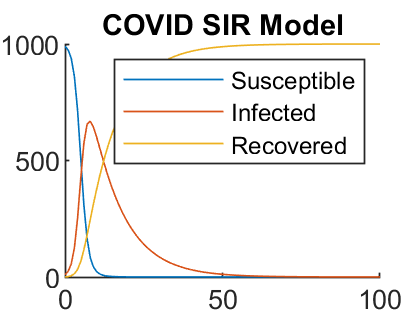


figure(2)
hold on
title('COVID SIR Model')
plot(Time_Step_1Day,COVID_S)
plot(Time_Step_1Day,COVID_I)
plot(Time_Step_1Day,COVID_R)
legend('Susceptible','Infected','Recovered')
xlim([0 100])
ylim([0 1000])
hold off

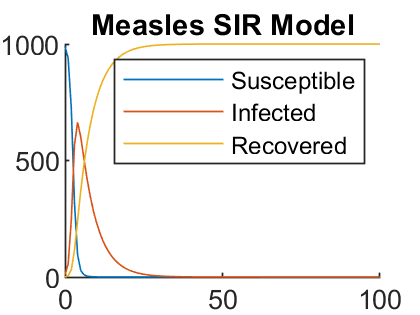


figure(3)
hold on
title('Measles SIR Model')
plot(Time_Step_1Day,Measles_S)
plot(Time_Step_1Day,Measles_I)
plot(Time_Step_1Day,Measles_R)
legend('Susceptible','Infected','Recovered')
xlim([0 100])
ylim([0 1000])
hold off

#### Discussion:

blah blah blah

## Part 2: Interpolation

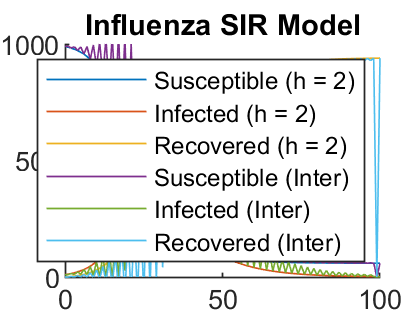

[Flu_S_Part2,Flu_I_Part2,Flu_R_Part2] = SIR_Model(990,10,0,100,2,Influenza_Tran_Rate,Influenza_Recov_Rate);
[Flu_S_Part2_Interpo,Flu_I_Part2_Interpo,Flu_R_Part2_Interpo] = Linear_Interpolation(Flu_S_Part2,Flu_I_Part2,Flu_R_Part2);

% THIS PLOT IS REDUNDANT AND NOT REQUIRED FOR SUBMISSION
Time_Step_2Day = 0:2:100;
figure(4)
hold on
title('Influenza SIR Model')
plot(Time_Step_2Day,Flu_S_Part2)
plot(Time_Step_2Day,Flu_I_Part2)
plot(Time_Step_2Day,Flu_R_Part2)
plot(Time_Step_1Day,Flu_S_Part2_Interpo)
plot(Time_Step_1Day,Flu_I_Part2_Interpo)
plot(Time_Step_1Day,Flu_R_Part2_Interpo)
legend('Susceptible (h = 2)','Infected (h = 2)','Recovered (h = 2)','Susceptible (Inter)','Infected (Inter)','Recovered (Inter)')
xlim([0 100])
ylim([0 1000])
hold off

%% EL2 Error for linear interpolation
% Broken at the moment
[Flu_S_EL2,Flu_I_EL2,Flu_R_EL2] = EL2_Error(Flu_S_Part2_Interpo,Flu_I_Part2_Interpo,Flu_R_Part2_Interpo,Flu_S,Flu_I,Flu_R);

## Part 3: Least-Squares

[ln_I, Initial_Infected_est, Tran_Rate_est, k_est, t_data, X, theta] = Linear_Least_Squares(990,10,0,30,1,Influenza_Tran_Rate,Influenza_Recov_Rate);
disp('Estimated Parameters:');

Estimated Parameters:


fprintf('I(0) (Estimated): %.2f\n', Initial_Infected_est);

I(0) (Estimated): 17.91


fprintf('k (Estimated): %.4f\n', k_est);

k (Estimated): 0.1149


fprintf('Tran_Rate (Estimated): %.4f\n', Tran_Rate_est);

Tran_Rate (Estimated): 0.2171


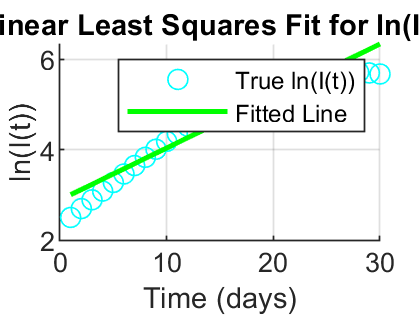


% Plot Results
figure(10);
scatter(t_data, ln_I, 'co', 'DisplayName', 'True ln(I(t))');
hold on;
plot(t_data, X * theta, 'g-', 'LineWidth', 1.5, 'DisplayName', 'Fitted Line');
xlabel('Time (days)');
ylabel('ln(I(t))');
title('Linear Least Squares Fit for ln(I(t))');
legend;
grid on;
hold off;


[ln_I_10, Initial_Infected_est_10, Tran_Rate_est_10, k_est_10, t_data_10, X_10, theta_10] = Linear_Least_Squares(990,10,0,10,1,Influenza_Tran_Rate,Influenza_Recov_Rate);
disp('Estimated Parameters:');

Estimated Parameters:


fprintf('I(0) (Estimated): %.2f\n', Initial_Infected_est);

I(0) (Estimated): 17.91


fprintf('k (Estimated): %.4f\n', k_est);

k (Estimated): 0.1149


fprintf('Tran_Rate (Estimated): %.4f\n', Tran_Rate_est);

Tran_Rate (Estimated): 0.2171



% Plot Results
figure(12);
scatter(t_data, ln_I, 'co', 'DisplayName', 'True ln(I(t))');
hold on;
plot(t_data, X * theta, 'g-', 'LineWidth', 1.5, 'DisplayName', 'Fitted Line');
xlabel('Time (days)');
ylabel('ln(I(t))');
title('Linear Least Squares Fit for ln(I(t))');
legend;
grid on;
hold off;

**Discussion**

Blah Blah Blah

## Part 4: Fourier Analysis

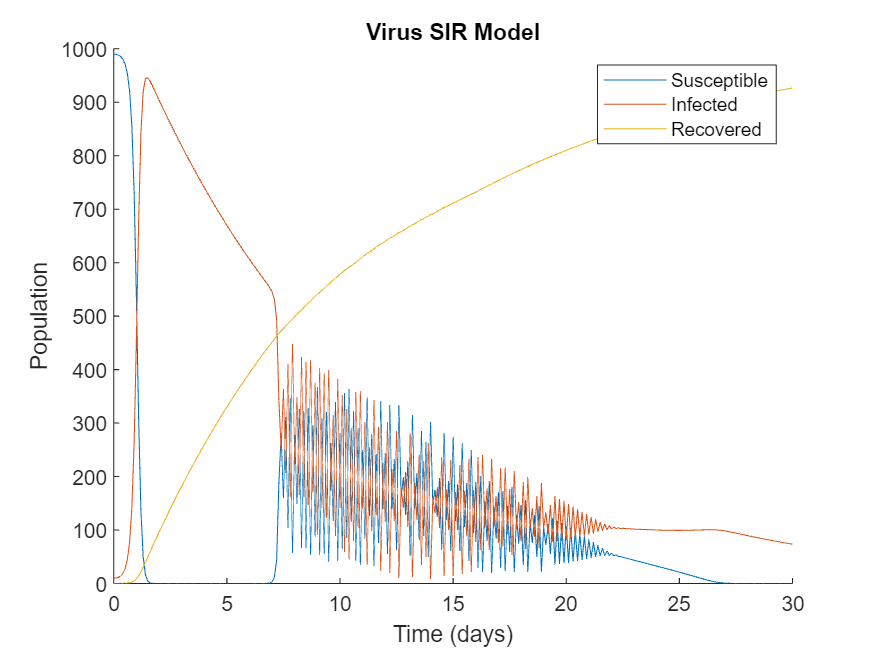

clear; clc; close all
Recov_Rate = 0.1;
Initial_Tran_Rate = 0.3;
Amplitude = 5;
Angular_Frequency = 2*pi;


[Virus_S,Virus_I,Virus_R,Time] = Periodic_SIR_Model(990,10,0,30,0.1,Recov_Rate,Initial_Tran_Rate,Amplitude,Angular_Frequency);



figure(1)
hold on
title('Virus SIR Model')
plot(Time,Virus_S)
plot(Time,Virus_I)
plot(Time,Virus_R)
legend('Susceptible','Infected','Recovered')
xlabel('Time (days)');
ylabel('Population');
xlim([0 30])
ylim([0 1000])
hold off

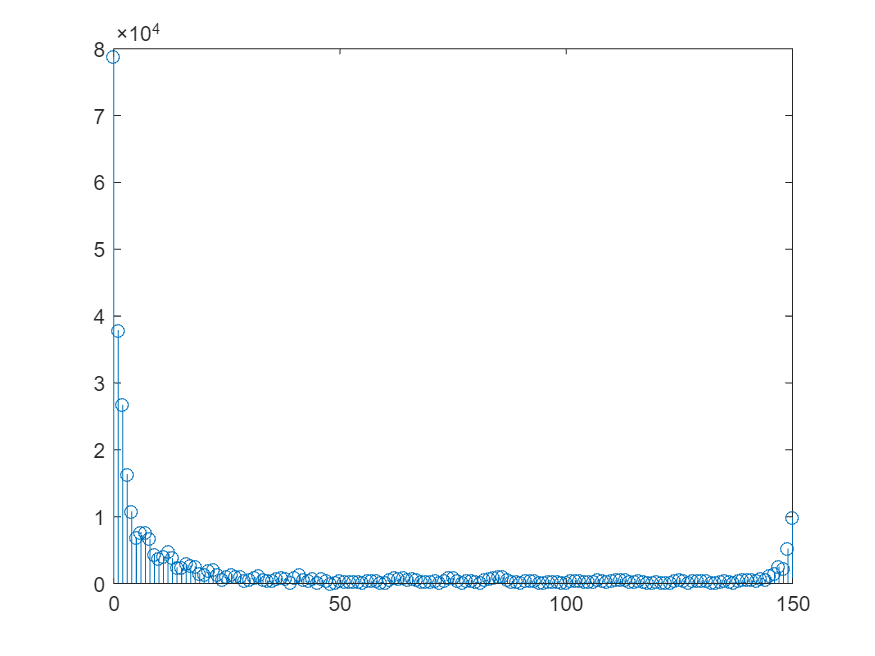


Y = fft(Virus_I);
k = 0:length(Virus_I)/2;
freq = k;

figure(2)
stem(freq, abs(Y(1:(length(Virus_I)/2)+1)));